## DC motor modeling

Based on : [https://ctms.engin.umich.edu/CTMS/index.php?example=MotorSpeed&section=SystemModeling](https://ctms.engin.umich.edu/CTMS/index.php?example=MotorSpeed&section=SystemModeling)

% motor params
J = 0.01        % kg*m^2

J = 0.0100

b = 0.10        % N*m*s

b = 0.1000

K = 0.01        % V/rad/s

K = 0.0100

R = 1           % Ohm

R = 1

L = 0.5         % H

L = 0.5000

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




% transfer function between speed and voltage
% P_omega = omega (s) / V (s)
P_omega = K / ( (J*s + b)*(L*s + R) + K^2 )

P_omega =
 
             0.01
  ---------------------------
  0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.



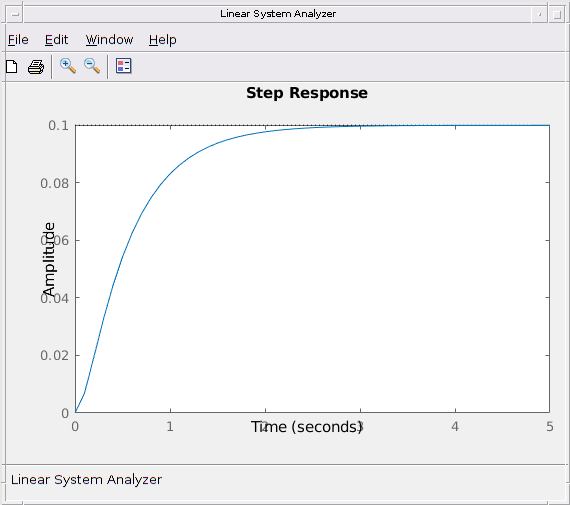

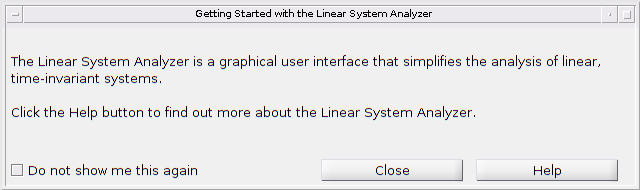

linearSystemAnalyzer('step', P_omega, 0:0.1:5);

# Get empiric data (speed control)

data = csvread("speed_test4.csv", 1, 0);

time = data(:,1);
voltage = data(:,2);
omega = data(:,3);

Ts = mean(diff(time))

Ts = 0.0100

print speed data

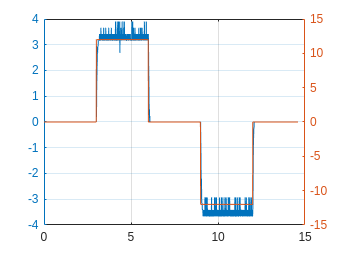

figure
yyaxis left
plot(time, omega)
hold on 
yyaxis right
plot(time, voltage)
grid on

estimate model

dc_data = iddata(omega, voltage, Ts);
tf_model = tfest(dc_data, 1, 0, 0)       % first order + integrator

tf_model =
  From input "u1" to output "y1":
    8.656
  ---------
  s + 30.55
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "dc_data".
Fit to estimation data: 92.84%                      
FPE: 0.02427, MSE: 0.02417                          
 
Model Properties


verify model against empiric data

omega_model = lsim(tf_model, voltage, time)   % u,t define the input signal

omega_model =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


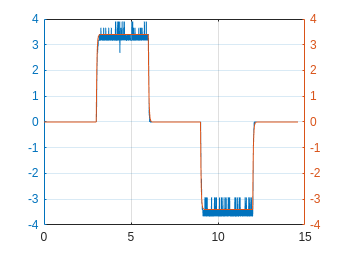


figure
yyaxis left
plot(time, omega)
hold on 
yyaxis right
plot(time, omega_model)
grid on

obtain PI coefficients

sys_d = c2d(tf_model, Ts)

sys_d =
  From input "u1" to output "y1":
   0.07459 z^-1
  ---------------
  1 - 0.7367 z^-1
 
Sample time: 0.01 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties



pidTuner(sys_d)     % z =0.85, tr = 3.0s

# Get empiric data (position control)

data = csvread("pos_test3.csv", 1, 0);

time = data(:,1);
voltage = data(:,2);
theta = data(:,3);

Ts = mean(diff(time))

Ts = 0.0100

print speed data

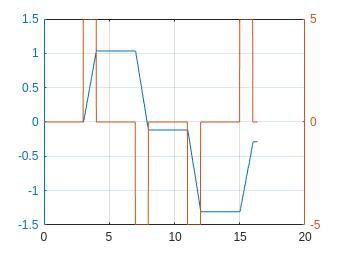

figure
yyaxis left
plot(time, theta)
hold on 
yyaxis right
plot(time, voltage)
grid on

estimate model

dc_data = iddata(theta, voltage, Ts);
tf_model = tfest(dc_data, 2, 0, 0)       % second order + integrator

tf_model =
  From input "u1" to output "y1":
           4.84
  ----------------------
  s^2 + 20.45 s + 0.2077
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "dc_data".
Fit to estimation data: 91.98%                      
FPE: 0.004038, MSE: 0.004014                        
 
Model Properties


verify model against empiric data


theta_model = lsim(tf_model, voltage, time)   % u,t define the input signal

theta_model =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


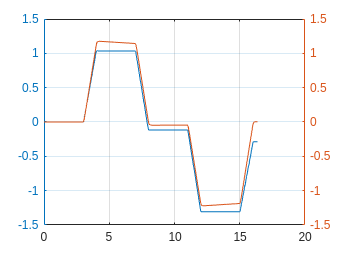


figure
yyaxis left
plot(time, theta)
hold on 
yyaxis right
plot(time, theta_model)
grid on

obtain PI coefficients

sys_d = c2d(tf_model, Ts)

sys_d =
  From input "u1" to output "y1":
  0.0002263 z^-1 + 0.0002114 z^-2
  -------------------------------
    1 - 1.815 z^-1 + 0.815 z^-2
 
Sample time: 0.01 seconds
Discrete-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 2
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties



pidTuner(sys_d)     % 